# Forecasting of coronavirus COVID19 epidemic (SIR model)

It is assumed that the model is a reasonable description of the one-stage epidemic. In particular, the model assumes a constant population, uniform mixing of the people, and equally likely recovery of infected. The model is data-driven, so its forecast is as good as data are. The forecasting change with new or changed data.

**DISCLAIMER**: Software and data is for education and not for medical or commercial use. The model may fail in some situations. In particular, the model may be unadequate, the model may fail in the initial phase and in when additional epidemic stages or outbreaks  (not described by SIR model) are encountered. Use it at your own discretion.

The data are only for demonstrating the operation of fitVirusCV19. FitVirus and presented demo data are only for educational and academic purposes and should not be used for medical purposes and in commerce. They are provided as is and any express or implied warranties, including but not limited to implied warranties of merchantability and fitness for a particular purpose are disclaimed.

**Source of data**

[https://ourworldindata.org/coronavirus-source-data.](https://ourworldindata.org/coronavirus-source-data.)

[https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina](https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina)

[https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory](https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory)

An actual source of data is for each country reported in the corresponding getData function.

**Notation**

$R$  Reproduction number ($=\frac{\beta }{\gamma }\left(1-\frac{C}{N}\right)$) ,i.e.. number of people infected by a patient

$R_0$  Basic reproduction number ($=\frac{\beta }{\gamma }$) 

$\beta$  Average contact frequency (1/day)

$\gamma$  Average removal frequency (1/day) 

$N$  Population size (approx. initial size  of susceptible population)

$C_{\textrm{end}}$  Epidemic size (total recovered population)

$S_{\textrm{end}}$  Final number  of susceptible individuals left 

**Report**

fprintf('Date: %s\n',datestr(date))  

Date: 12-May-2020


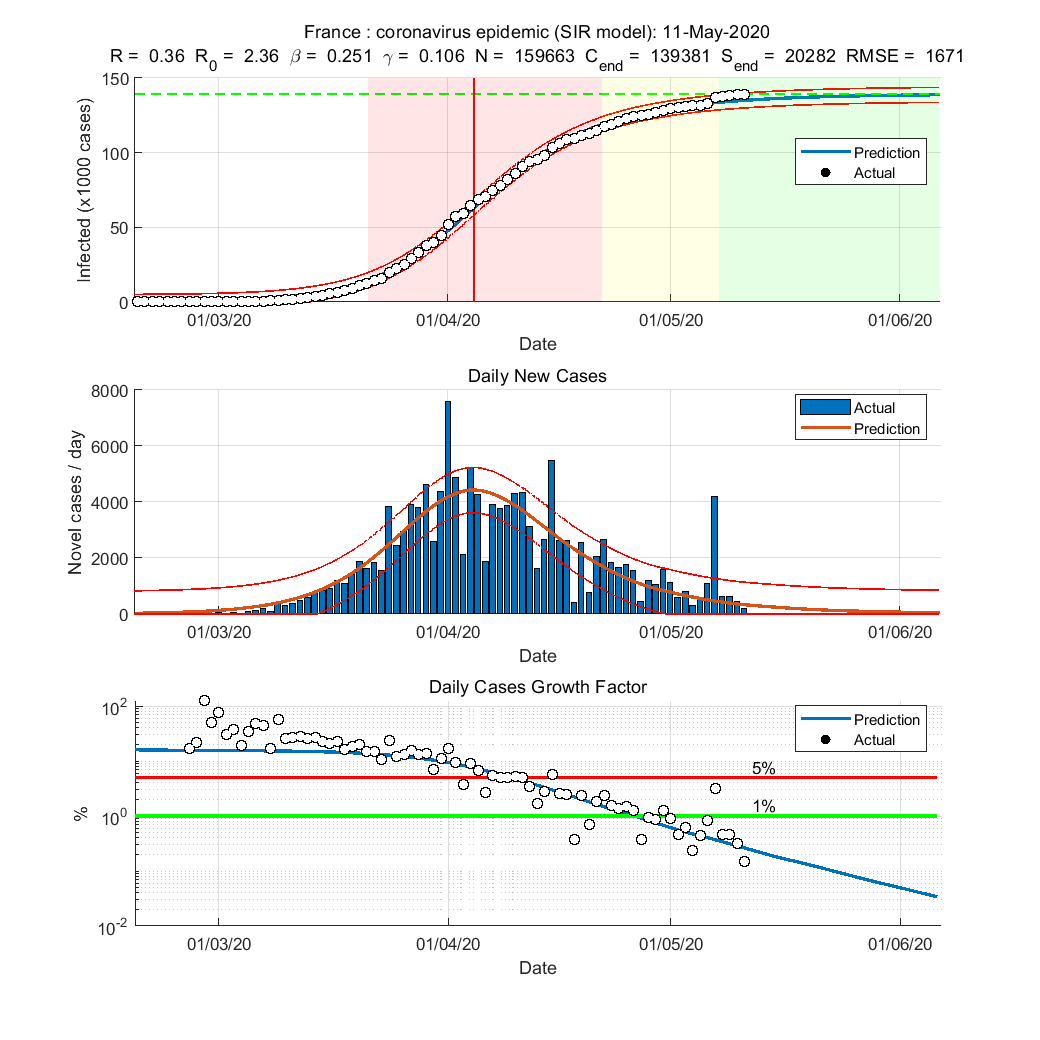

Epidemic modeling by susceptible-infected-recovered (SIR) model
  Country                       France
  Day                           103
Estimated the SIR model parameters
  Contact frequency (beta)      0.251 (1/day)
  Removal frequency (gamma)     0.106 (1/day)
  Population size (N)           159662
  Initial number of cases (I0)  5
Basic rep. number         (R0)  2.364
Reproduction number       (R )  0.364
End reproduction number         0.3
Time between contacts     (Tc)  4 (day)
Infectious period         (Tr)  9.4 (day)
Final state
  Final number of cases         139380
  Final number of susceptibles  20281
Daily forecast for 12-May-2020
  Total                         NaN
  Increase                      NaN
Estimated logistic model parameters
  Epidemic size (K)             116824 (cases)
  Epidemic rate (r)             0.144774 (1/day)
  Initial doubling time         4.8 (day)
Estimated duration (days)
  Turning day                   65
  Acceleration   phase          14 (days

res = fitVirusCV19(@getDataFrance,'prn','on','nsp',3);

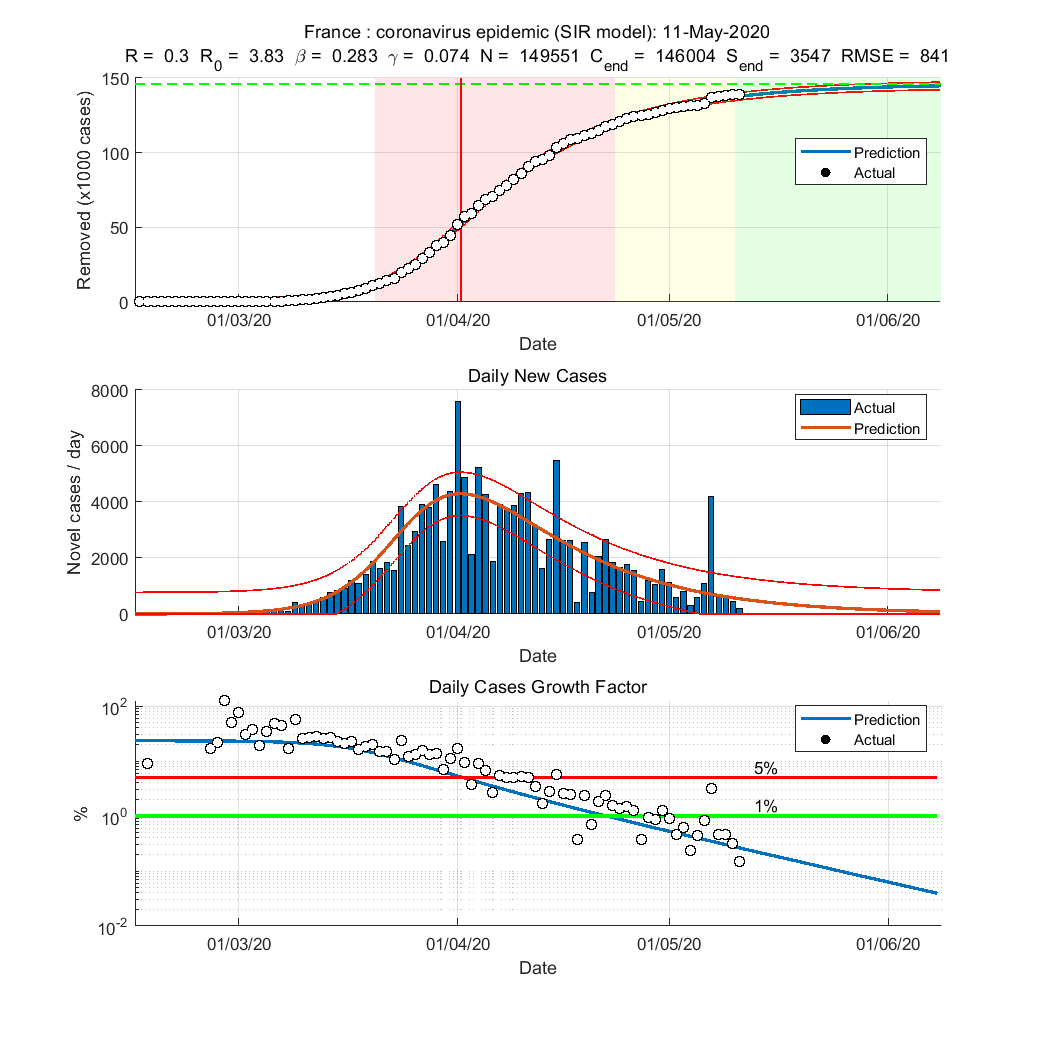

Epidemic modeling by susceptible-infected-recovered (SIR) model
  Country                       France
  Day                           103
Estimated the SIR model parameters
  Contact frequency (beta)      0.283 (1/day)
  Removal frequency (gamma)     0.074 (1/day)
  Population size (N)           149550
  Initial number of cases (I0)  1
Basic rep. number         (R0)  3.832
Reproduction number       (R )  0.301
End reproduction number         0.091
Time between contacts     (Tc)  3.5 (day)
Infectious period         (Tr)  13.5 (day)
Final state
  Final number of cases         146003
  Final number of susceptibles  3546
Daily forecast for 12-May-2020
  Total                         NaN
  Increase                      NaN
Estimated logistic model parameters
  Epidemic size (K)             127112 (cases)
  Epidemic rate (r)             0.209333 (1/day)
  Initial doubling time         3.3 (day)
Estimated duration (days)
  Turning day                   63
  Acceleration   phase          12 (

% assume that daily reports contains removed cases
res = fitVirusCV19R(@getDataFrance,'prn','on','nsp',3);